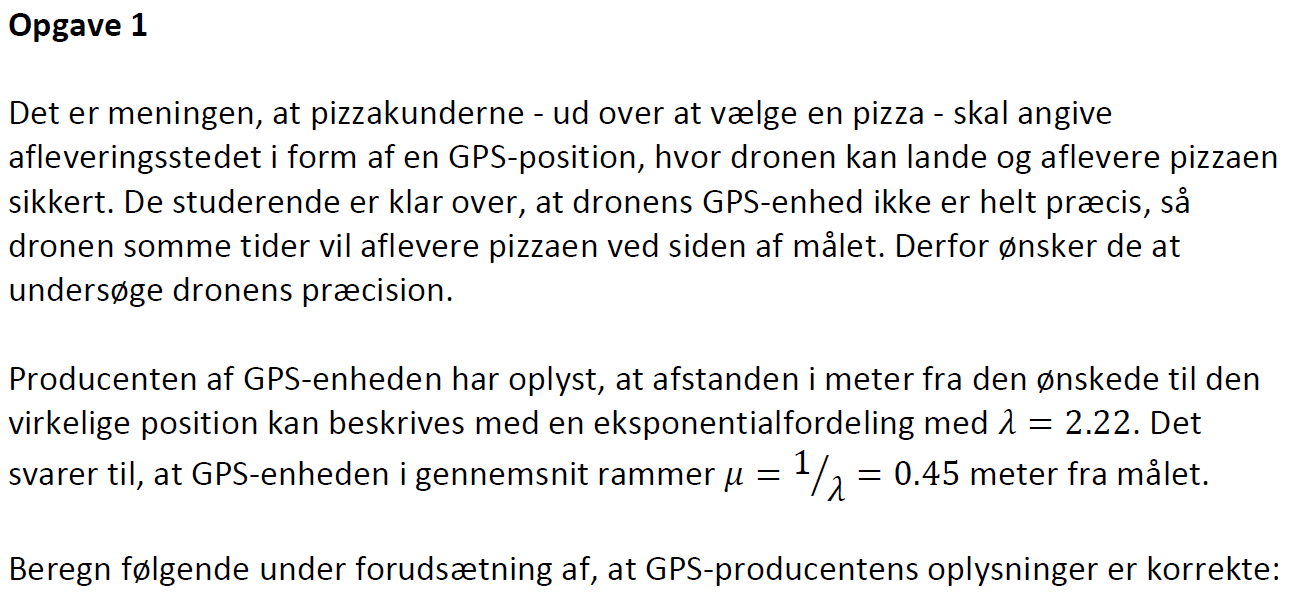

### a)

Sandsynligheden for at dronen lander indenfor en meter fra målet.

clear
lambda = 2.22; % 
mu = 1/lambda; %
y = 1; % m


 Dette er den selv udregnede version

syms x
F = lambda * exp(-lambda*x); % den comulerede
F_int = int(F,0,1);
vpa(F_int,4)

$$ans = 0.8914$$

P_1 = expcdf(y, mu)

P_1 = 0.8914

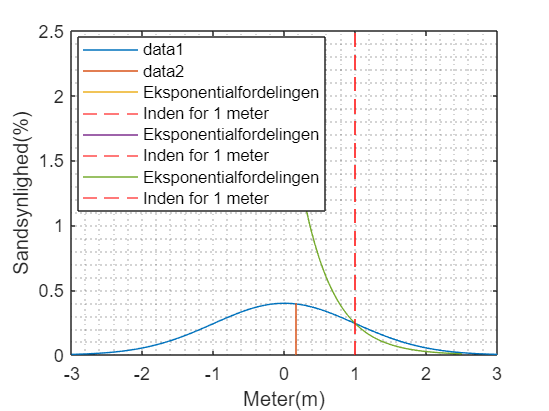

Y = linspace(0,2.5,100);
P = exppdf(Y, mu);
plot(Y, P,'DisplayName', 'Eksponentialfordelingen')
% xline(P_1)
xline(y, 'r--', DisplayName='Inden for 1 meter')
ylabel('Sandsynlighed(%)')
xlabel('Meter(m)')
legend('location', 'best')%, 'northeastoutside')
grid("minor")



nmean = mu;
x = [0:0.1:1];
on_left_side = x <= nmean;
left_x = x(on_left_side);
left_y = norm(on_left_side);

Error using norm
First argument must be single or double.

patch_x = [left_x(:); left_x(end); left_x(1)];
patch_y = [left_y(:); left_y(1); left_y(1)];
h = patch(patch_x, patch_y, 'w');
hatchfill(h);

### b)

Sandsynligheden for at dronen lander mellem 1 og 2 meter fra målet.

P_1_2 = expcdf(2, mu) - P_1

### c)

Sandsynligheden for at dronen lander mere end 2 meter fra målet.

help hatchfill


hatchfill not found.

Use the Help browser search field to search the documentation, or
type "help help" for help command options, such as help for methods.




P_2_inf = 1 - expcdf(2, mu)

P_2_inf = 0.0118

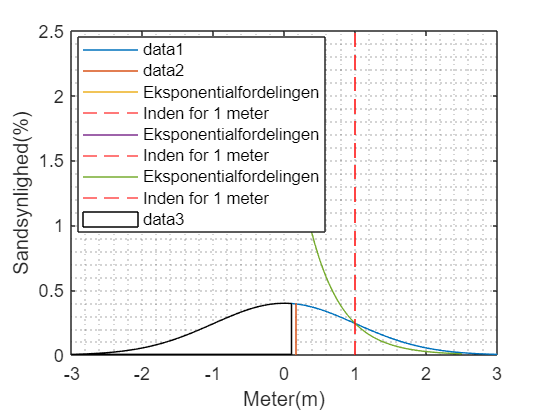

x = [-3:.1:3];
norm = normpdf(x,0,1);


nmean = mean(norm);
on_left_side = x <= nmean;
left_x = x(on_left_side);
left_y = norm(on_left_side);
patch_x = [left_x(:); left_x(end); left_x(1)];
patch_y = [left_y(:); left_y(1); left_y(1)];
h = patch(patch_x, patch_y, 'w');

hatchfill(h);

Unrecognized function or variable 'hatchfill'.


figure;
plot(x,norm)
y1 = get(gca,'ylim');
hold on
plot([mean(norm) mean(norm)],y1)
